# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 17-Oct-2024 20:19:03

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["t", "x", "y", "vx", "vy"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("C:\Users\papas\Downloads\Perros.csv", opts);

## Convert to output type

t = tbl.t;
x = tbl.x;
y = tbl.y;
vx = tbl.vx;
vy = tbl.vy;

## Clear temporary variables

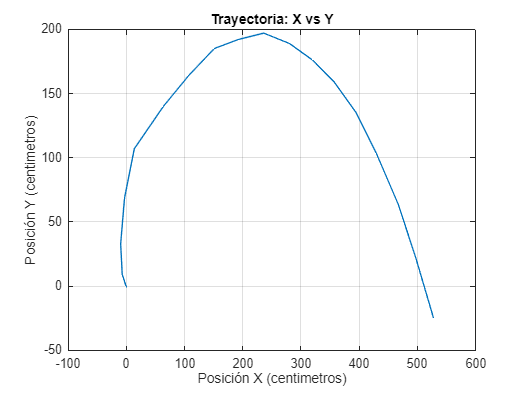

clear opts tbl
% Gráfica de Trayectoria (X, Y)
figure;
plot(x, y);
title('Trayectoria: X vs Y');
xlabel('Posición X (centimetros)');
ylabel('Posición Y (centimetros)');
grid on;

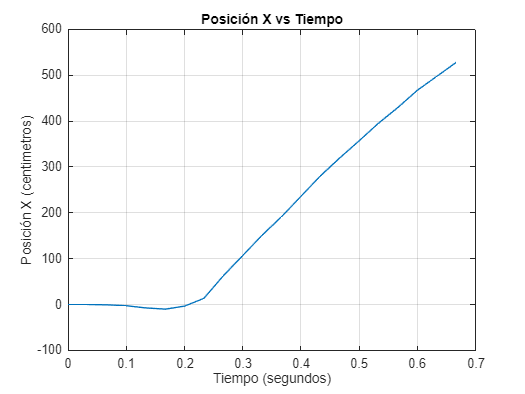

% Gráfica de posición en X vs Tiempo
plot(t, x);
title('Posición X vs Tiempo');
ylabel('Posición X (centimetros)');
xlabel('Tiempo (segundos)');
grid on;

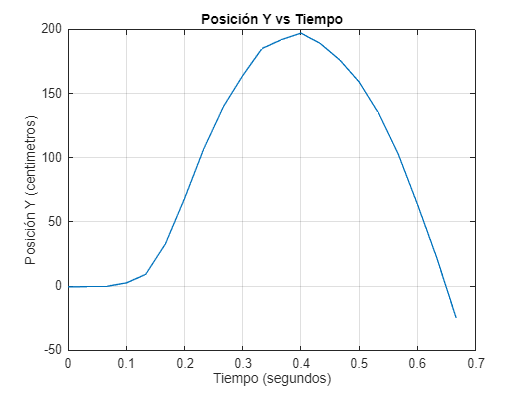

% Gráfica de posición en Y vs Tiempo
plot(t, y);
title('Posición Y vs Tiempo');
xlabel('Tiempo (segundos)');
ylabel('Posición Y (centimetros)');
grid on;

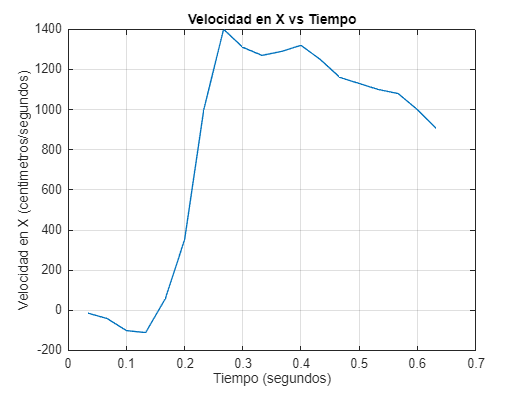

% Gráfica de velocidad en X vs Tiempo
plot(t, vx);
title('Velocidad en X vs Tiempo');
xlabel('Tiempo (segundos)');
ylabel('Velocidad en X (centimetros/segundos)');
grid on;

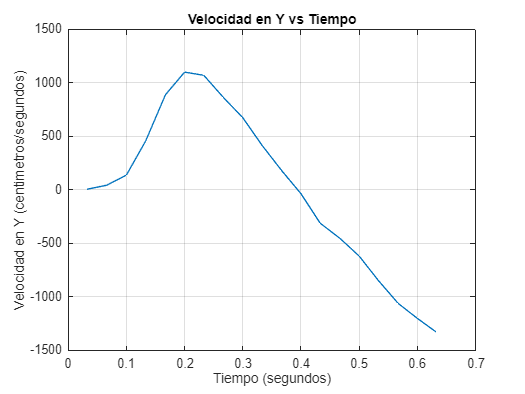

% Gráfica de velocidad en Y vs Tiempo
plot(t, vy);
title('Velocidad en Y vs Tiempo');
xlabel('Tiempo (segundos)');
ylabel('Velocidad en Y (centimetros/segundos)');
grid on;

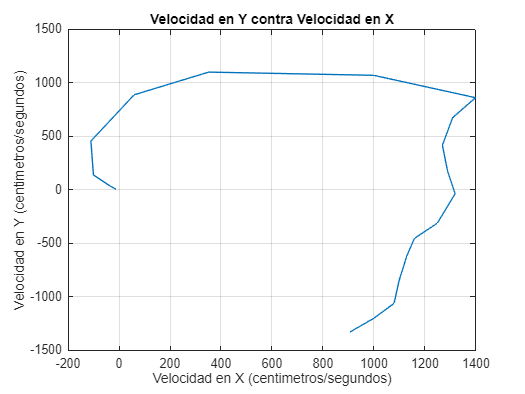

% Grafica de la velocidad en Y contra velocidad en X
plot(vx,vy)
title('Velocidad en Y contra Velocidad en X')
xlabel('Velocidad en X (centimetros/segundos)')
ylabel('Velocidad en Y (centimetros/segundos)')
grid on